# Interpolacion de Vandermonde

clear
tic
clc
syms x
format rat
%Vector alpha
alpha=[2 3 4]

alpha =        2              3              4       


%Valores f(x)
y=[4 2 8]

y =        4              2              8       


n=length(alpha);
%Forma 1(a b c)(vander)
%Forma 2(c b a)(ciclo)
forma=1;
if(forma==1)
    V=zeros(n);
    for i=1:n
        for j=1:n
            V(i,j)=alpha(i)^(j-1);
        end
    end
    V
    inversa=inv(V)
    solucion=inversa*y'
    a=solucion(3)
    b=solucion(2)
    c=solucion(1)
elseif(forma==2)
    V=vander(alpha)
    inversa=inv(V)
    solucion=inversa*y'
    a=solucion(1)
    b=solucion(2)
    c=solucion(3)
end

V =        1              2              4       
       1              3              9       
       1              4             16       


inversa =        6             -8              3       
      -7/2            6             -5/2     
       1/2           -1              1/2     


solucion =       32       
     -22       
       4       


a =        4       


b =      -22       


c =       32       


modelo=a*x^2+b*x+c

$$modelo = 4\,x^{2}-22\,x+32$$

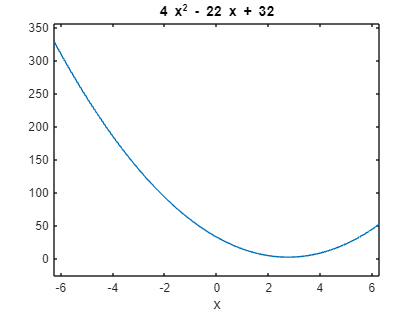

ezplot(modelo)

toc

Elapsed time is 0.508858 seconds.
